**Terminal 1**

Calibração e Conexão GP3

close all;
clear all;

%% Generate path to GP3 subfolders
[mainDir,~,~] = fileparts(mfilename('fullpath'));
addpath(genpath(mainDir));

% Criar conexão 1 
conexao_1 = tcpip('127.0.0.1', 4242);
conexao_1.InputBufferSize = 4096;
fopen(conexao_1);
conexao_1.Terminator = 'CR/LF';

%% Realizar a Calibração
StartCalibration(conexao_1);

fprintf(conexao_1, '<GET ID="CALIBRATE_RESULT_SUMMARY" />');
while  conexao_1.BytesAvailable > 0
 dataReceived = fscanf(conexao_1);
 disp(dataReceived)
end

outputFileName = 'teste1_piscada_03_12.txt';

Executar a Gravação da Mensagem User no GP3

SendMsgToGP3(conexao_1,'');
fprintf(conexao_1, '<SET ID="ENABLE_SEND_USER_DATA" STATE="1" />');
fprintf(conexao_1, '<SET ID="ENABLE_SEND_DATA" STATE="1" />');
SendMsgToGP3(conexao_1,'START_RECORDING')

Criar novo terminal

if exist([pwd '/RecordGP3Data.m'],'file')
    % run this if the GP3 functions are in the same folder as the main
    % script
    fn_args = CreateInputfn_args(varargin{:});
    eval(['!matlab -nosplash -nodesktop -r "terminal2_coletarET(''' outputFileName fn_args ''')" &'])
else
    % run this if the GP3 functions are in a sub-folder of the main script
    fn_args = CreateInputfn_args(varargin{:});
    eval(['!matlab -nosplash -nodesktop -r "addpath(genpath(pwd)); terminal2_coletarET(''' outputFileName fn_args ''')" &'])
end

errCode = 0


fprintf('\nConnecting with session 2 client. Please wait...\n\n')
pause(.05)

Esperar até a segunda sessão estar aberta através do reconhecimento da chave "CLIENT2_READY" no GP3

inicio = tic; %momento de começo do loop
while 1
    dataReceived = fscanf(conexao_1);
    split = strsplit(dataReceived, '"');
    USER_message = split{end-1};
    if strcmp(USER_message, 'CLIENT2_READY')
        fprintf('\nMensagem enviada pelo terminal 2 reconhecida. \n\n')
        break
    end
    if toc (inicio) > 120
        error('Conexão GP3 e segundo terminal falhou.')

ERROR: TG_Connect() returned -2.

    end
end

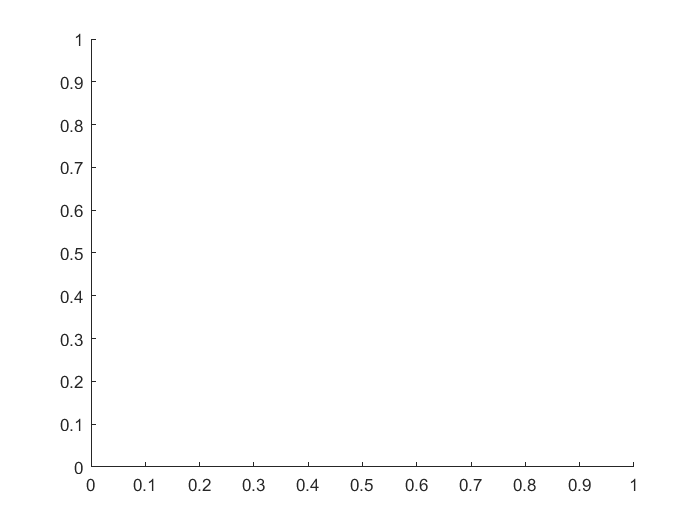

Error using sprintf
Unable to convert 'matlab.graphics.primitive.Text' value to 'char' or 'string'.

%re-read lib
try
    unloadlibrary thinkgear

catch 
    warning('biblioteca ainda nao carregada')

Unrecognized function or variable 'filename'.

end 
loadlibrary('thinkgear.dll');

%esperar conexão ser estabelecida no MATLAB
%% Generate path to GP3 subfolders
[mainDir,~,~] = fileparts(mfilename('fullpath'));
addpath(genpath(mainDir));

%% Set-up Matlab to GP3 session1 socket
session1_client = ConnectToGP3;

%% connect to mindwave
portnum1 =      4;      %COM port#
comPortName1 =  sprintf('\\\\.\\COM%d', portnum1);

TG_BAUD_115200 =      115200; 
TG_STREAM_PACKETS =       0;
TG_DATA_RAW =             4;

connectionId1 = calllib('thinkgear', 'TG_GetNewConnectionId');
if ( connectionId1 < 0 )
    error ('ERROR: TG_GetNewConnectionId() returned %d.\n', connectionId1)
end

%set/open stream (raw bytes) log file for connection
errCode = calllib('thinkgear', 'TG_SetStreamLog', connectionId1, 'streamLog.txt' )
if( errCode < 0 )
    error( 'ERROR: TG_SetStreamLog() returned %d.\n', errCode )
end

%set/open data (thinkgear values) log file for connection
errCode = calllib('thinkgear', 'TG_SetDataLog', connectionId1, 'dataLog.txt' );
if( errCode < 0 )
    error( 'ERROR: TG_SetDataLog() returned %d.\n', errCode );
end


%errCode = calllib('thinkgear', 'TG_Connect',  connectionId1,comPortName1,TG_BAUD_57600,TG_STREAM_PACKETS);
errCode = calllib('thinkgear', 'TG_Connect',  connectionId1,comPortName1,TG_BAUD_115200,TG_STREAM_PACKETS);
if ( errCode < 0 )
    error( 'ERROR: TG_Connect() returned %d.\n', errCode);
end

%to save data from all columns
seg = 20
linhas = seg * 512
data = ones(linhas, 6);

%% Spawn a second Matlab session2 that records GP3 data to output file
outputFileName = 'piscada2.txt';
ExecuteRecordGP3Data(session1_client,outputFileName);


j = 0;
i = 0;
while (i < 51200)   %loop for 60 seconds
    if (calllib('thinkgear','TG_ReadPackets',connectionId1,1) == 1)   %if a packet was read...
        
            if (calllib('thinkgear','TG_GetValueStatus',connectionId1,TG_DATA_RAW) ~= 0)   %if RAW has been updated 
                j = j + 1;
                i = i + 1;
                data(j) = calllib('thinkgear','TG_GetValue',connectionId1,TG_DATA_RAW);
                total(i) = calllib('thinkgear','TG_GetValue',connectionId1,TG_DATA_RAW);
                SendMsgToGP3(session1_client, num2str(calllib('thinkgear','TG_GetValue',connectionId1,TG_DATA_RAW)));
            end
    end
    
    
    if (j == 256)
        modPlotRAW(data);            %plot the data, update every .5 seconds (256 points)
        j = 0;
    end
    
end

raw = total; %return value of data

calllib('thinkgear', 'TG_FreeConnection', connectionId1 );